clear all
close all
clc

t = cell(1,125);
th1 = cell(1,125);
th2 = cell(1,125);
th3 = cell(1,125);
th1d = cell(1,125);
th2d = cell(1,125);
th3d = cell(1,125);

comX = cell(1,125);
comY = cell(1,125);

m = [];
l = [];
c = [];

maxY = [];


for i = 1:125
    fileName = "L_1_COM_" + i + ".txt";
    filePath = "Mar_23_2023_Single_Length_Set_2/" + fileName;

    currParams = readmatrix(filePath,"Range",[3 1 3 9]);
    l = [l; currParams(1:3)];
    c = [c; currParams(4:6)];
    m = [m; currParams(7:9)];
    
    data = readmatrix(filePath,"NumHeaderLines",5);

    q1 = data(:,2);
    q2 = data(:,3);
    q3 = data(:,4);
    
    t{i} = data(:,1);
    th1{i} = data(:,2);
    th2{i} = data(:,3);
    th3{i} = data(:,4);
    th1d{i} = data(:,5);
    th2d{i} = data(:,6);
    th3d{i} = data(:,7);
    
    comX{i} = (m(i,1)*c(i,1)*cos(q1) + m(i,2)*(l(i,1)*cos(q1) + c(i,2)*cos(q1+q2)) + m(i,3)*(l(i,1)*cos(q1) + l(i,2)*cos(q1+q2) + c(i,3)*cos(q1+q2+q3)))/sum(m(i,:));
    comY{i} = (m(i,1)*c(i,1)*sin(q1) + m(i,2)*(l(i,1)*sin(q1) + c(i,2)*sin(q1+q2)) + m(i,3)*(l(i,1)*sin(q1) + l(i,2)*sin(q1+q2) + c(i,3)*sin(q1+q2+q3)))/sum(m(i,:));


    maxY = [maxY; max(comY{i})];

end


maxY = reshape(maxY,5,25)';

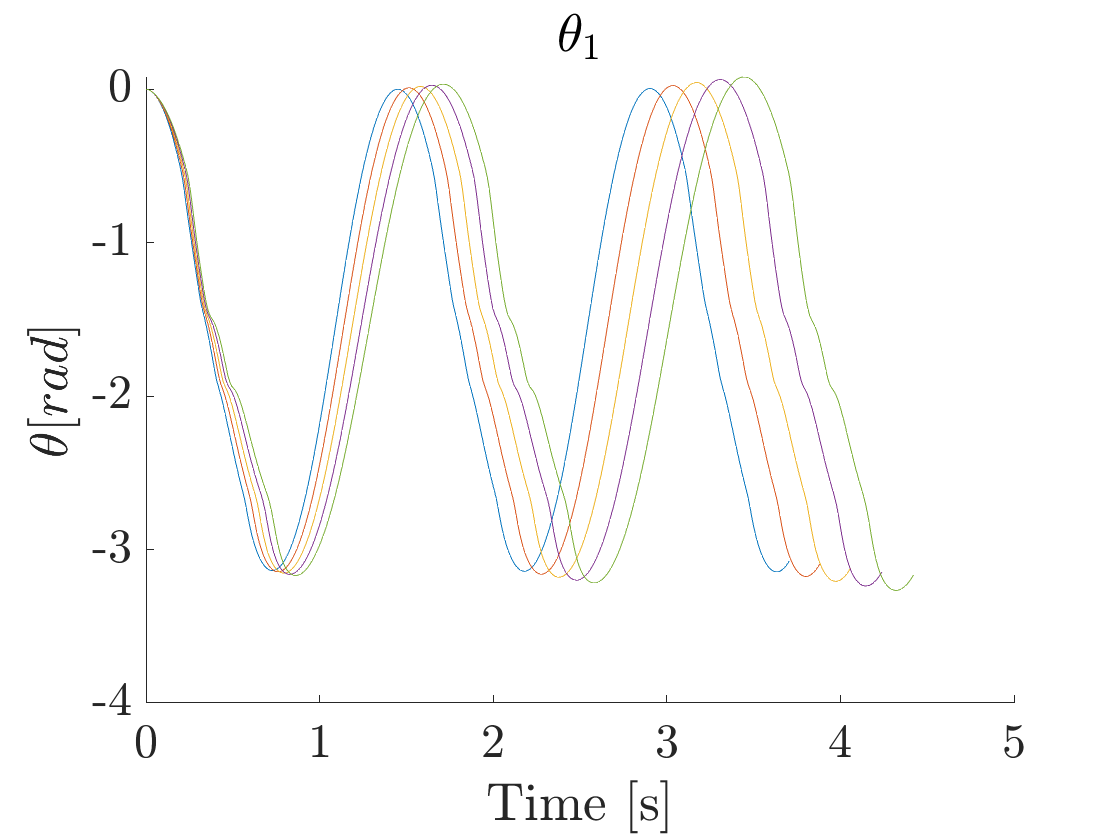

figure();
hold on
for i = 1:5
    plot(t{i},th1{i});
end
hold off
ylabel('$\theta [rad]$');
xlabel('Time [s]');
title('$\theta_1 $')

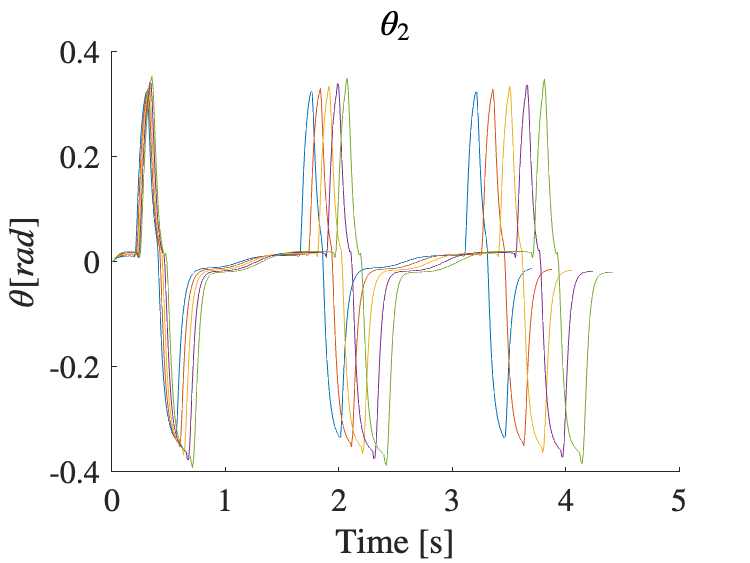


figure();
hold on
for i = 1:5
    plot(t{i},th2{i});
end
hold off
ylabel('$\theta [rad]$');
xlabel('Time [s]');
title('$\theta_2 $')

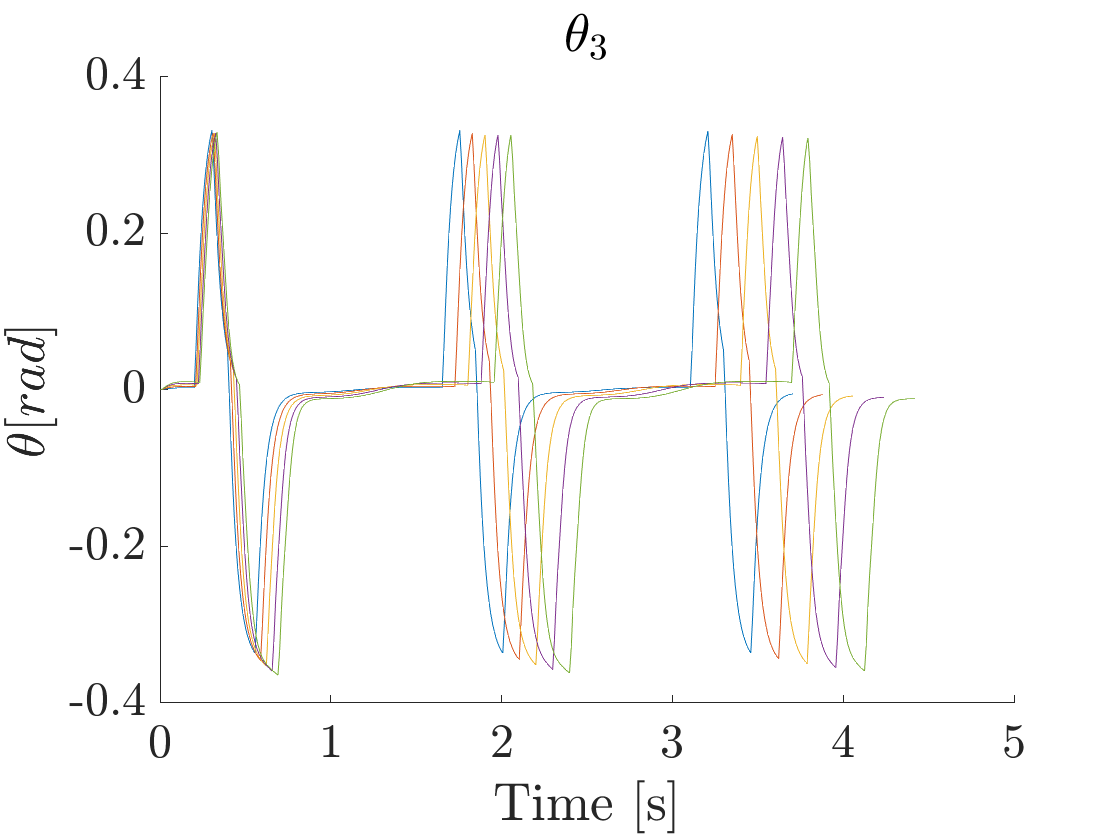


figure();
hold on;
for i = 1:5
    plot(t{i},th3{i});
end
hold off;
ylabel('$\theta [rad]$');
xlabel('Time [s]');
title('$\theta_3 $')

## Max height of COM

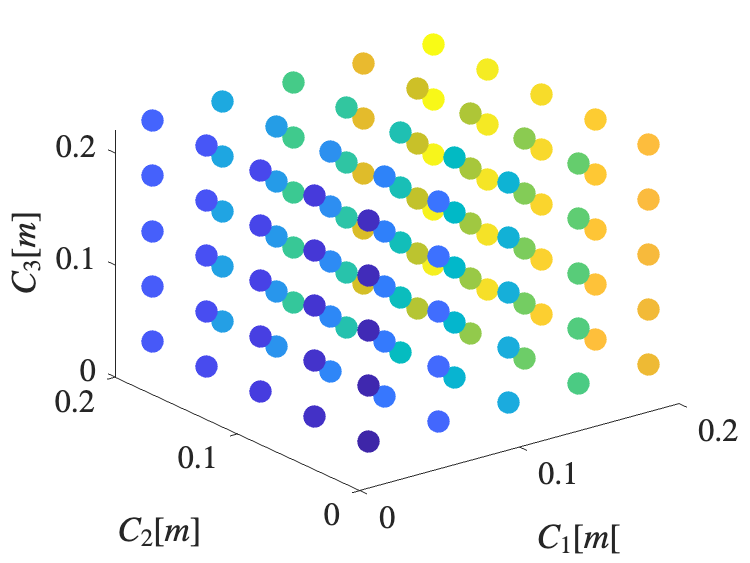

maxY = reshape(maxY',125,1);
colorSort = [maxY c parula(125)];
colorSort = sortrows(colorSort,1,'ascend');

figure();
hold on;
maxHeight = max(maxY);
minHeight = min(maxY);
range = maxHeight - minHeight;
for i = 1:125
    plot3(colorSort(i,2),colorSort(i,3),colorSort(i,4),'.','MarkerSize',50,'Color',colorSort(i,5:7));
end
hold off;
view(3)
xlabel('$C_1 [m[$','interpreter','latex');
ylabel('$C_2 [m]$');
zlabel('$C_3 [m]$');
colormap('parula');

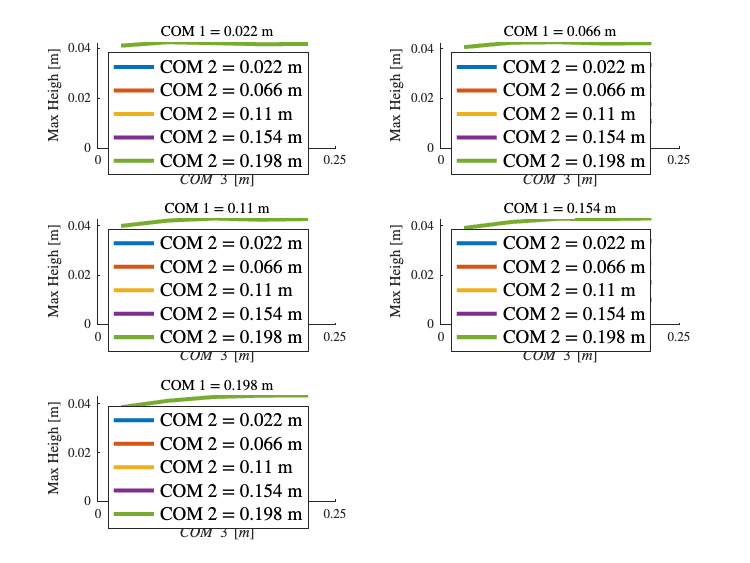



maxY = reshape(maxY,5,25)';

figure();
tiledlayout('flow');
for i = 1:5
    nexttile();
    hold on;
    plot(c(5*(i-1) + 1:5*i,3),maxY(5*(i-1) + 1:5*i,:),'linewidth',3);
    xlabel('$COM \, \, 3 \, \, [m]$','Interpreter','latex');
    ylabel('Max Heigh [m]');
    title("COM 1 = " + c(25*(i-1) + 1,1) + " m");
    legend("COM 2 = " + c(5,2) + " m","COM 2 = " + c(10,2) + " m",...
        "COM 2 = " + c(15,2) + " m","COM 2 = " + c(20,2) + " m",...
        "COM 2 = " + c(25,2) + " m",'location','nw','fontsize',14);
end

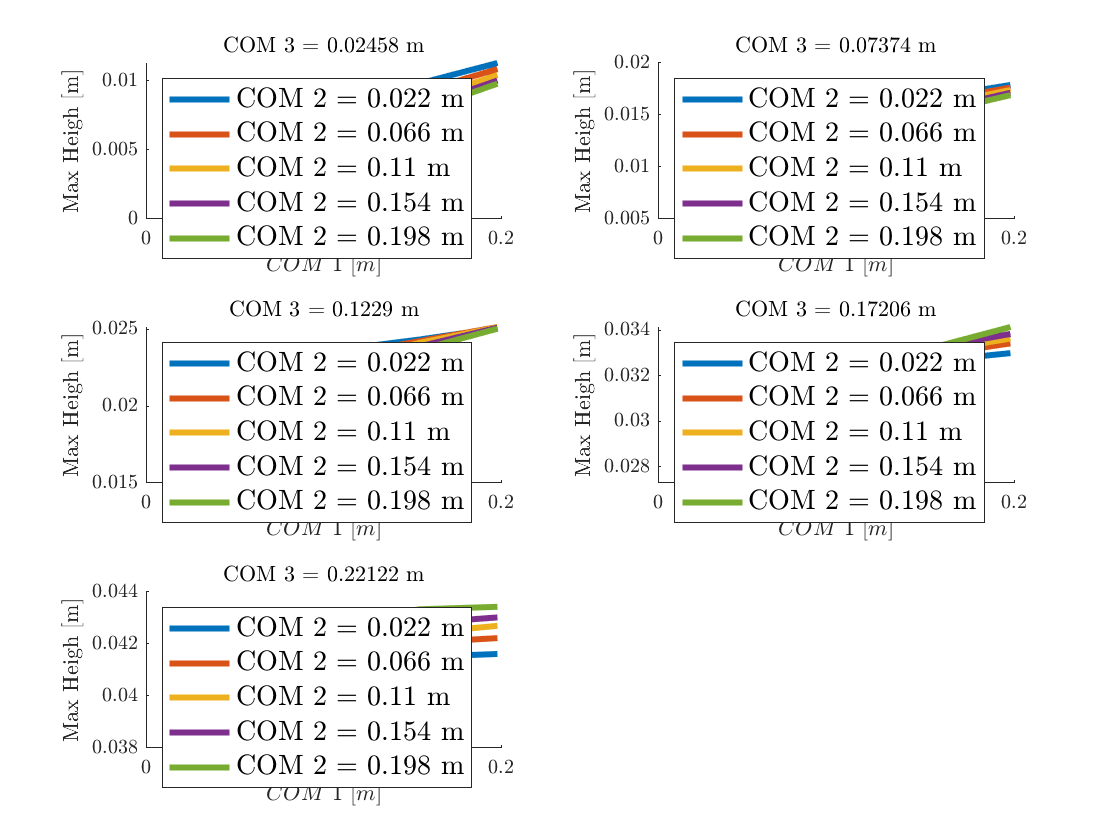


maxY = reshape(maxY',125,1);
dataSortMat = [c maxY];
dataSortMat = sortrows(dataSortMat,[3 2],'ascend');
c = flip(dataSortMat(:,1:3),2);
maxY = dataSortMat(:,4);
maxY = reshape(maxY,5,25)';

figure();
tiledlayout('flow');
for i = 1:5
    nexttile();
    hold on;
    plot(c(5*(i-1) + 1:5*i,3),maxY(5*(i-1) + 1:5*i,:),'linewidth',3);
    xlabel('$COM \, \, 1 \, \, [m]$','Interpreter','latex');
    ylabel('Max Heigh [m]');
    title("COM 3 = " + c(25*(i-1) + 1,1) + " m");
    legend("COM 2 = " + c(5,2) + " m","COM 2 = " + c(10,2) + " m",...
        "COM 2 = " + c(15,2) + " m","COM 2 = " + c(20,2) + " m",...
        "COM 2 = " + c(25,2) + " m",'location','nw','fontsize',14);
end